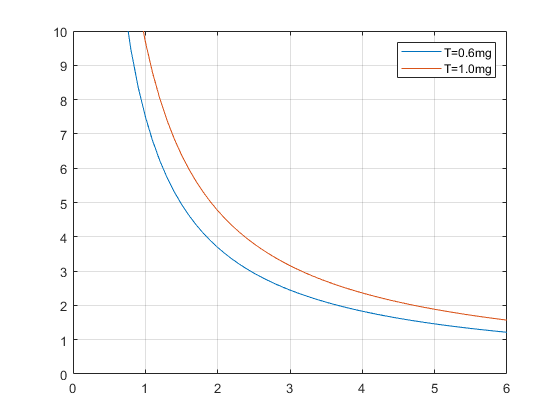

z=[0.3	0.4	0.5	0.6	0.7	0.8	0.9	1	1.1	1.2	1.3	1.4	1.5	1.6	1.7	1.8	1.9	2	2.1	2.2	2.3	2.4	2.5	2.6	2.7	2.8	2.9	3	3.1	3.2	3.3	3.4	3.5	3.6	3.7	3.8	3.9	4	4.1	4.2	4.3	4.4	4.5	4.6	4.7	4.8	4.9	5	5.1	5.2	5.3	5.4	5.5	5.6	5.7	5.8	5.9	6];
g=9.8;
T=0.145*g;
rou=1.21;
A=pi*(0.05/2)^2;
L=2*0.058;
Cax=4.672;
Z0=0.033;
Crad=60.808;
Vmax1=zeros(1,58);
for i=1:58
   Vmax1((i))=sqrt(T/(2*rou*A))*Cax*L/(z(i)-Z0);
end


Vmax2=zeros(1,58);
for i=1:58
   Vmax2((i))=sqrt(0.6*T/(2*rou*A))*Cax*L/(z(i)-Z0);
end
plot(z,Vmax2,"LineStyle","-");hold on;plot(z,Vmax1,'DisplayName','Vmax1');hold off;
legend({'T=0.6mg','T=1.0mg'});
xlim([0 6]);
ylim([0 10]);
set(gca,'XGrid','on','YGrid','on');

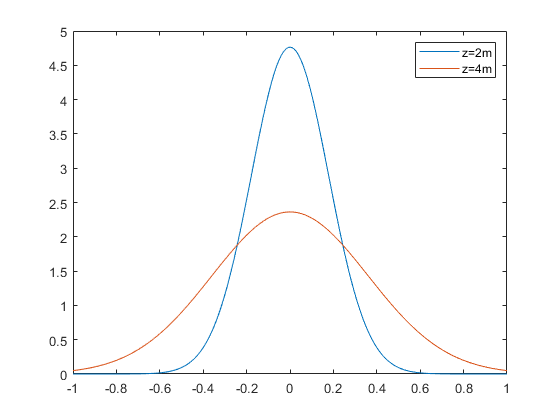


v_z2=zeros(1,101);
v_z4=zeros(1,101);
r=(-1:0.01:1);
for i=1:201
    v_z2(i)=Vmax1(18)*exp(-Crad*(r(i)/(z(18)-Z0))^2);
    v_z4(i)=Vmax1(38)*exp(-Crad*(r(i)/(z(38)-Z0))^2);
end
plot(r,v_z2,r,v_z4);
legend({'z=2m','z=4m'});